# ** MODELO DE INVASIÓN ZOMBIE**

Karen Melissa Zuluaga Quintero

Ecuaciones diferenciales, informe #3

C2366-CM0235-2495

Profesora: Olga Lucía Quintero Montoya

ID: 1097910206

# **INTRODUCCIÓN**

Los métodos numéricos son un conjunto de técnicas matemáticas que se utilizan para calcular una solución numérica aproximada a un problema específico. En otras palabras, implican una serie de cálculos diseñados para obtener una solución numérica precisa con una precisión razonable. En este informe, aplicaremos el método de Runge Kutta para modelar una invasión zombie, haciendo referencia al modelo SIRV (Susceptibles, Infectados, Recuperados y Vacunados) y analizaremos cómo se comporta el modelo al aumentar el número de poblaciones en la simulación.

# **OBJETIVO GENERAL**

Abordar de manera numérica la resolución de la ecuación no lineal que describe el comportamiento de un modelo de invasión zombie aplicado al modelo SIRV (Susceptibles, Infectados, Recuperados y Vacunados) y posteriormente realizar un análisis detallado y conciso de los resultados obtenidos.

 **Modelo a implementar: **


$$\frac{ds}{dt} = -\beta si - \delta s\\
\frac{di}{dt} = \beta si - \gamma i\\
\frac{dr}{dt} = \gamma i\\
\frac{dv}{dt} = \delta s$$


- **Variables a utilizar:**

        $\beta:$ tasa de transmisión

        $\gamma :$ tasa de recuperación

        $\delta :$ tasa de vacunación

**Valores:**

    
$$\beta = 0.1$$
 
$$\gamma = 0.02$$
 
$$\delta = 0.001$$
  
$$s(0) = 0.8$$
 
$$i(0) = 0.1$$
 
$$r(0) = 0$$
 
$$v(0) = 0.1$$
 

**1. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?**

Por medio de bloque de código, se definirán las variables a emplear durante cada ítem del informe, por lo que se define las ecuaciones de estado que modela al sistema y se resolverá por el comando ode45 que nos permite aproximar nuestros valores numéricos para obtener una interpretación analítica del modelo invasivo.

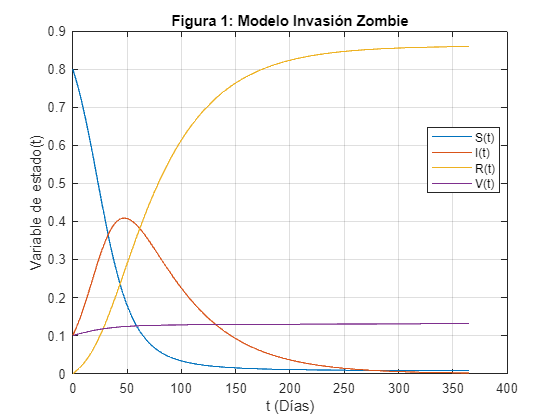

syms S(t) I(t) R(t) V(t)

% Parametros
Beta = 0.1; Gamma = 0.02; Delta= 0.001;

% Ecuaciones
SZombies = -Beta*S*I-Delta*S;
IZombies = Beta*I*S-Gamma*I;
RZombies = Gamma*I;
VZombies = Delta*S;
%usamos el comando ode45 para resolver
Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);

% Metodo numerico
Ts = 1;
tmin = 0;
tmax = 365;
tspan = tmin:Ts:tmax;

% Condiciones iniciales
Ci_Zombies = [0.8 0.1 0 0.1]; 

% solucion método numérico 
figure(1)
[tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_Zombies);
plot(tiempo,Salida)
title('Figura 1: Modelo Invasión Zombie')
xlabel('t (Días)')
ylabel('Variable de estado(t)')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','best')

Se puede inferir que, en el punto de intersección entre las curvas que representan las poblaciones de zombies susceptibles y recuperados corresponde al punto más alto de la cantidad de zombies infectados.

 La presencia de un solo pico se debe al agotamiento gradual de zombies susceptibles, ya que pasan a la población de zombies infectados. Si se incrementara el número de zombies vacunados en dicha población, esto tendría como efecto una disminución en las poblaciones de zombies infectados y recuperados, lo que resultaría en un pico de infectados mucho más bajo en comparación con la situación en la que hay menor cantidad de zombies vacunados.

- ***¿Qué ocurre si cambio v(0)?***

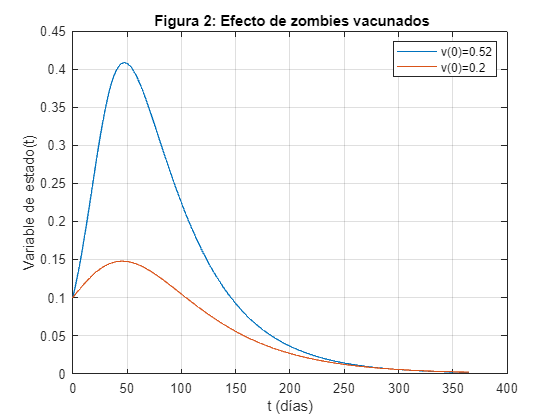

v0 = 0.52; 
Ci_Zombies = [0.9-v0 0.1 0 v0]; 
[tiempo2,Salida2] = ode45(Funciones_estado,tspan,Ci_Zombies);
plot(tiempo,Salida(:,2),tiempo2,Salida2(:,2))
title(' Figura 2: Efecto de zombies vacunados')
xlabel('t (días)')
ylabel('Variable de estado(t)')
grid on
legend({['v(0)=' num2str(v0)],'v(0)=0.2'})

En la última representación gráfica, se muestra la evolución de la cantidad de zombies infectados a lo largo del tiempo, considerando dos niveles de vacunación distintos: uno del 10% y otro del 52%. Se puede observar claramente que cuando se implementa una tasa de vacunación más alta, el pico de zombies infectados disminuye de manera considerable. Además, es esencial destacar que aquellos que han sido vacunados ya no son susceptibles a la enfermedad, lo que significa que evitan las etapas de infectados y recuperados.

Para lograr que el porcentaje de zombies infectados alcance únicamente un 15% de la población, se necesita una tasa de vacunación del 52%. Esta medida no solo reduce significativamente la magnitud del pico de infectados, sino que también protege a un gran número de individuos al hacer que sean inmunes a la enfermedad.

**2. Graficar sólo la solución i(t) con un aumento sólo de i(0) y usando al menos 5 valores. Observar que al cambiar i(0) cambia s(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1.**

*Observar el efecto negativo al tener inicialmente una población mayor de zombies infectados.

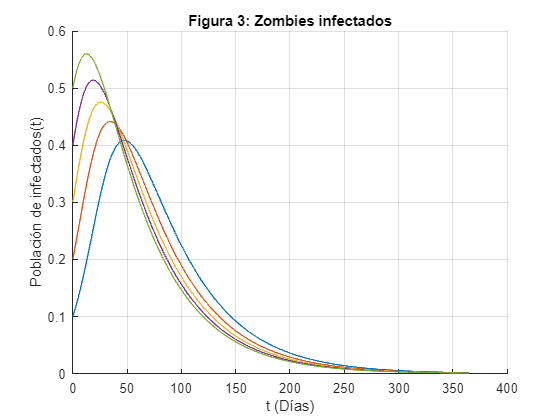

syms S(t) I(t) R(t) V(t)

% Parametros
Beta = 0.1; Gamma = 0.02; Delta= 0.001;

% Ecuaciones
SZombies = -Beta*S*I-Delta*S;
IZombies = Beta*I*S-Gamma*I;
RZombies = Gamma*I;
VZombies = Delta*S;
%usamos el comando ode45 para resolver
Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);

% Metodo numerico
Ts = 1;
tmin = 0;
tmax = 365;
tspan = tmin:Ts:tmax;

% Condiciones iniciales
Variab_Zomb = [0.8 0.1 0 0.1
              0.7 0.2 0 0.1
              0.6 0.3 0 0.1
              0.5 0.4 0 0.1
              0.4 0.5 0 0.1];

% solucion método numérico 
figure
for k = 1:length(Variab_Zomb)
    [tiempo,Salida] = ode45(Funciones_estado,tspan,Variab_Zomb(k,:));
    hold on
    plot(tiempo, Salida(:,2))
    title('Figura 3: Zombies infectados')
    xlabel('t (Días)')
    ylabel('Población de infectados(t)')
    grid on
end

Cuando se reduce la cantidad inicial de zombies infectados en el contexto del modelo SIRV, observamos que el punto máximo de la propagación de la enfermedad se retrasa en el tiempo, lo que implica que se necesita más tiempo para alcanzar su punto más alto. Esto se debe a que, al haber menos zombies infectados al principio, la población de zombies susceptibles se mantiene mayor, ya que la mayoría de los individuos aún no han sido afectados.

Por otro lado, si aumentamos el número de infectados en el modelo, esto resulta en una disminución de la población  de zombies susceptible. Esto se debe a que la población susceptible disminuye significativamente, ya que la mayoría de los zombies se encuentran en la categoría de infectados al inicio del proceso de modelado. Esto afecta la velocidad de propagación de la enfermedad y puede dar lugar a un pico más temprano en la curva epidémica.

**3.**  **Graficar sólo la solución i(t) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados**.

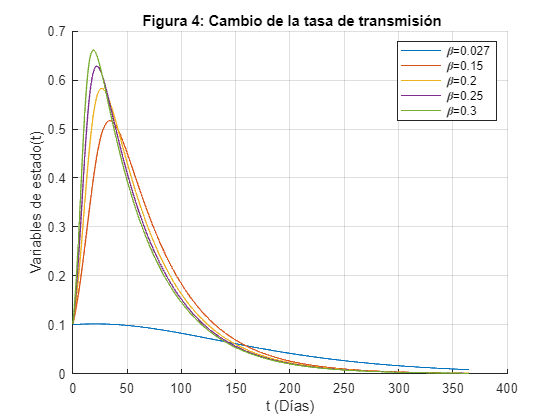

syms S(t) I(t) R(t) V(t)

% Parametros
Beta = [0.027 0.15 0.20 0.25 0.30]; 
Gamma = 0.02; 
Delta= 0.001;

% Ecuaciones
RZombies = Gamma*I;
VZombies = Delta*S;
%usamos el comando ode45 para resolver
Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);

% Metodo numerico
Ts = 1;
tmin = 0;
tmax = 365;
tspan = tmin:Ts:tmax;

% Condiciones iniciales
Ci_Zombies = [0.8 0.1 0 0.1]; 

% solucion método numérico 
figure (4)
for k = 1:length(Beta)
    SZombies = -Beta(k)*S*I-Delta*S;
    IZombies = Beta(k)*I*S-Gamma*I;
    Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);
    [tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_Zombies);
    hold on
    plot(tiempo,Salida(:,2))
    title(' Figura 4: Cambio de la tasa de transmisión')
    xlabel('t (Días)')
    ylabel('Variables de estado(t)')
    grid on
end
legend({'\beta=0.027','\beta=0.15','\beta=0.2','\beta=0.25','\beta=0.3'})

La tasa de transmisión requerida para prevenir una epidemia sería de 0.027. Esto refleja la capacidad de la enfermedad para propagarse; en otras palabras, cuanto más alta sea esta tasa, mayor será la población de zombies infectada, ya que la enfermedad se disemina con mayor facilidad.

Cuando analizamos la gráfica, se observa una marcada diferencia entre las distintas tasas de transmisión. La tasa de 0.027 se caracteriza por tener un pico de infectados más reducido. Aunque esta tasa de transmisión puede prolongar la duración de la propagación de la enfermedad, la cantidad de zombies afectados por el virus será considerablemente menor en comparación con las otras tasas de transmisión. Para evitar una epidemia, es necesario reducir la tasa de transmisión (beta) a un valor por debajo de 1. Si beta es menor que 1, la enfermedad se propagará a un ritmo más lento y eventualmente disminuirá. Esto se debe a que, en promedio, cada zombie infectado transmitirá la enfermedad a menos de una persona adicional. En términos de interpretación de los resultados, se puede afirmar que cualquier valor de beta por debajo de 1 evitaría una epidemia. Cuanto más cercano a cero sea el valor de beta, menor será la propagación de la enfermedad. Sin embargo, es esencial encontrar un equilibrio, ya que si beta es demasiado pequeño, la enfermedad podría extinguirse antes de que se alcance la inmunidad colectiva, lo que podría dar lugar a brotes futuros.

**4. Graficar sólo la solución i(t) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia?**

**Cambio de **$\gamma$

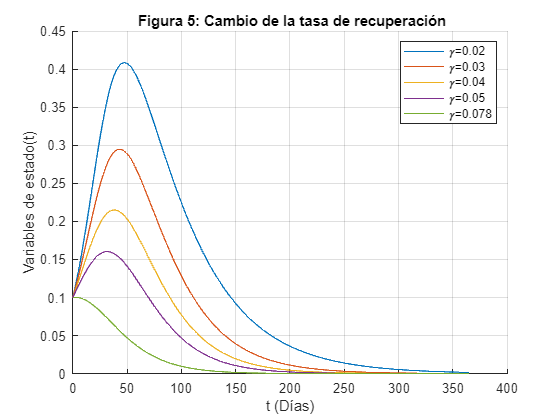

syms S(t) I(t) R(t) V(t)

% Parametros
Beta = 0.1; 
Gamma = [0.02 0.03 0.04 0.05 0.078]; 
Delta= 0.001;

% Ecuaciones
SZombies = -Beta*S*I-Delta*S;
VZombies = Delta*S;

% Metodo numerico
Ts = 1;
tmin = 0;
tmax = 365;
tspan = tmin:Ts:tmax;

% Condiciones iniciales
Ci_Zombies = [0.8 0.1 0 0.1]; 


% solucion método numérico 
figure (5)
for k = 1:length(Gamma)
   IZombies = Beta*I*S-Gamma(k)*I;
   RZombies = Gamma(k)*I;
    Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);
    [tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_Zombies);
    hold on
    plot(tiempo,Salida(:,2))
    title(' Figura 5: Cambio de la tasa de recuperación')
    xlabel('t (Días)')
    ylabel('Variables de estado(t)')
    grid on
end
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.05','\gamma=0.078'})

Cuando la tasa de recuperación es alta, como en el caso de 0.078, se observa un pico de enfermedad prácticamente insignificante, ya que los zombies se recuperan mucho más rápidamente de la enfermedad. Por el contrario, cuando la tasa de recuperación es baja, se registra un pico significativamente más alto en la cantidad de zombies infectadas en comparación con otras tasas, y este fenómeno se extiende en el tiempo, lo que significa que la enfermedad persiste durante un período más prolongado.

***5. Graficar sólo la solución i(t) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? ***

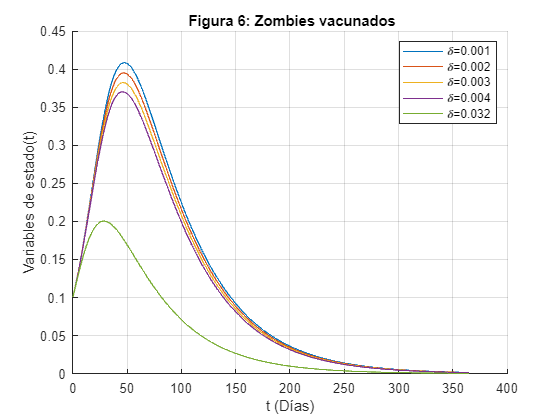

syms S(t) I(t) R(t) V(t)

% Parametros
Beta = 0.1; 
Gamma = 0.02; 
Delta= [0.001 0.002 0.003 0.004 0.032];

% Ecuaciones
IZombies = Beta*I*S-Gamma*I;
RZombies = Gamma*I;

% Metodo numerico
Ts = 1;
tmin = 0;
tmax = 365;
tspan = tmin:Ts:tmax;

% Condiciones iniciales
Ci_Zombies = [0.8 0.1 0 0.1];

% solucion método numérico 
figure(6)
for k = 1:length(Delta)
    SZombies = -Beta*S*I-Delta(k)*S;
    VZombies = Delta(k)*S;
    Funciones_estado = odeFunction([SZombies IZombies RZombies VZombies],[S I R V]);
    [tiempo,Salida] = ode45(Funciones_estado,tspan,Ci_Zombies);
    hold on
    plot(tiempo,Salida(:,2))
    title(' Figura 6: Zombies vacunados')
    xlabel('t (Días)')
    ylabel('Variables de estado(t)')
    grid on
end
legend({'\delta=0.001','\delta=0.002','\delta=0.003','\delta=0.004','\delta=0.032'})

A medida de que la tasa de vacunación aumente en la población de zombies, la enfermedad se manifiesta y se expande de manera menos significativa y rápida. Esto resulta en una disminución tanto de la población susceptible como de la población infectada. Para lograr que el pico de la enfermedad alcance un máximo del 20%, se necesita una tasa de vacunación mínima de 0.032. Esto significa que un nivel de vacunación por encima de este valor contribuirá a mantener el pico de infectados por debajo del 20%.

# **CONCLUSIONES**

En el desarrollo de este informe, fue posible comprender cómo funciona el modelado matemático de una invasión zombie y cómo se aplican los métodos numéricos en esta situación. También hemos comprendido la importancia de cada parámetro y su relevancia en el mundo real. En este contexto:

La tasa de propagación de los zombies (beta) en el modelo SIRV juega un papel crucial en la expansión de la amenaza zombie. Reducir esta tasa puede ayudar a controlar y prevenir la propagación de la invasión zombie, ya que limita la velocidad a la que se propagan los zombies. Si hay menos zombies al principio, la cantidad de personas susceptibles a ser convertidas en zombies aumenta, lo que puede retrasar el punto máximo de la invasión zombie.

Aumentar la tasa de vacunación en la población tiene un impacto positivo en la reducción de la propagación de los zombies. La vacunación disminuye la cantidad de personas susceptibles y, en consecuencia, reduce el número de personas que se convierten en zombies. Para asegurar que el punto máximo de la invasión zombie sea bajo, es necesario implementar una tasa de vacunación elevada.

La variación en las tasas de transmisión y vacunación tiene un efecto significativo en la dinámica de la invasión zombie. Tasas de transmisión más bajas y tasas de vacunación más altas conducen a un punto máximo de amenaza zombie más bajo y a una propagación más lenta de la invasión.

Este enfoque computacional también destaca la importancia de las medidas de salud pública, como la vacunación y el control de la transmisión, en la gestión y prevención de invasiones zombie. En resumen, podemos concluir que la aplicación de métodos numéricos es una herramienta poderosa que puede describir y predecir eventos en diferentes contextos, incluyendo situaciones de invasión zombie, y su aplicación es crucial en diversas áreas del conocimiento.